Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Dynamic aperture (Section 11.2)

Volker Ziemann, 211120

In this example we follow particles in two transverse planes and iterate Equation 11.4 in order to find the dynamic aperture, shown in Figure 11.2, in cases where the non-linearity, a single sextupole, is well centered in the beam pipe and when it is misaligned.

We determine the dynamic aperture by testing whether the particle survives `NN=1000` iterations. Then we select the horizontal and vertical tunes, `Qx` and `Qy`, respectively, and define the transfer matrix R, which is a simple rotation matrix in this case. 

clear all; close all
NN=1000;    % maximum number of turns
Qx=0.31; Qy=0.28;
R1D=@(mu)[cos(mu),sin(mu);-sin(mu),cos(mu)];
R=[R1D(2*pi*Qx),zeros(2);zeros(2),R1D(2*pi*Qy)];
hold on

#### Sextupole not misaligned

First we consider the system without misalignment and probe the dynamic aperture along a line in the transverse $(x,y)$ space defined by $x=r \cos\phi$ and $y=r\sin\phi$. 

for phi=0:pi/100:pi   % loop over angles phi

We start by choosing $r$ very large and then iteratively increase it by $dr=r/2$ depending on whether the particle with starting coordinates $x_0=r\cos\phi$ and $y_0=r\sin\phi$ survived NN turns or not. We repeat this procedure by halving the size of the interval `nmax=12` times. 

  nmax=12; dr=10; r=dr;
  while (nmax)        % scan radially
     dr=0.5*dr;
     x0=r*cos(phi); y0=r*sin(phi);  % new starting coordinates

The function `survived_turns()`, defined in the Appendix, interates Equation 11.4 for a maximum on `NN` turns and returns the maximum number of turns that the particle survived.

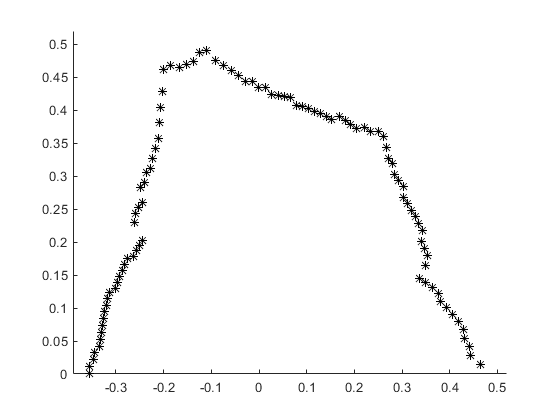

     if (survived_turns(NN,R,x0,y0,0,0)==NN), r=r+dr; else, r=r-dr; end

     nmax=nmax-1;
  end

The value of $(x_0,y_0)$ thus determined show the largest starting coordinates along a line, defned by the angle $\phi$for which a particles survives NN turns. We show this point by a black asterisk in transverse $(x,y)$ space.

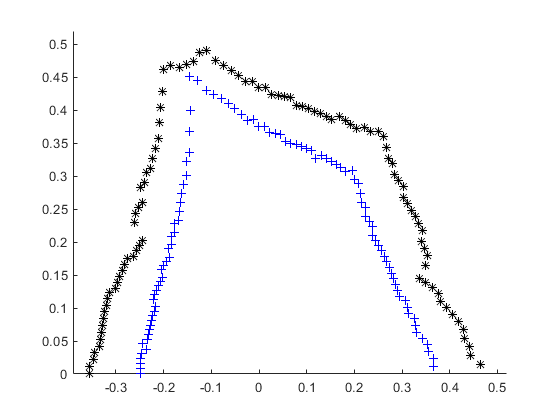

  plot(x0,y0,'k*');      
end
ylim([0,0.52]); xlim([-0.39,0.52])  

#### Sextupole misaligned by dx=-0.05

Now we repat the same procedure, but horizontally displace the sextupole by `dx=-0.05`, which we pass as an argument to the function survived_turns(). In this way we find the dynamic aperture for the configuration with the misaligned sextupole, which plot as a blue plus sign. We find that the dynamic aperture, which defines the boundary between particle trajectories that are stable and those that are unstable, has become smaller.

for phi=0:pi/100:pi         % loop over angles phi
  nmax=12; dr=10; r=dr;
  while (nmax)              % scan radially
     dr=0.5*dr;
     x0=r*cos(phi); y0=r*sin(phi);
     if (survived_turns(NN,R,x0,y0,-0.05,0)==NN), r=r+dr; else, r=r-dr; end
     nmax=nmax-1;
  end
  plot(x0,y0,'b+');
end

#### Sextupole misaligned by dx=-0.1

And in a third pass we increase the misalignement to `dx=-0.1`, repeat the procedure, and plot the dynamic aperture as red crosses. We observe that it has become even smaller.

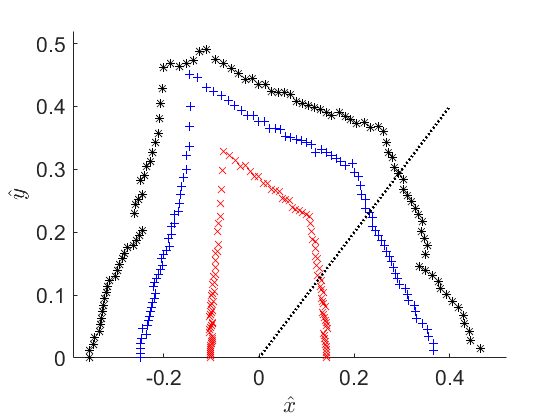

for phi=0:pi/100:pi  % dx=-0.1, dy=0
  nmax=12; dr=10; r=dr;
  while (nmax)
     dr=0.5*dr;

     x0=r*cos(phi); y0=r*sin(phi);
     if (survived_turns(NN,R,x0,y0,-0.1,0)==NN), r=r+dr; else, r=r-dr; end
     nmax=nmax-1;
  end
  plot(x0,y0,'rx');
end

After the three dynamic apertures for `dx=0,-0.05`, and` -0.1` are displayed, we annotate the axes.

plot([0,0.4],[0,0.4],'k:','LineWidth',2)
xlabel('$\hat x$','interpreter','latex'); 
ylabel('$\hat y$','interpreter','latex');
set(gca,'FontSize',16);

#### Survived turns along $\phi=45^o$

Now we want to determine the number of turns that a particle survives as a function of its starting coordinates located on a line with coordinates $x_0=r\cos\phi$ and $y_0=r\sin\phi$ where $\phi=45^o$. The starting positions are indicated on the previous plot by the diagonal dotted line. Here  we therefore define the angle `phi` and the starting values for` r` and allocate an array `turns` in which we store the survived turns for each starting coordinate. We do so for the same misalignments `dx` considered above.

phi=45*pi/180;
r=2:-0.0001:0.1; 
turns=zeros(3,length(r));

Now we loop over the radial positions r, define starting coordinates x0 and y0 and use the function survived_turns() to store the found value in the array turns.

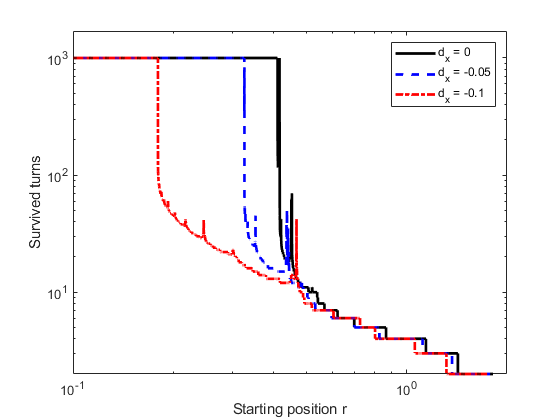

for k=1:length(r)
  x0=r(k)*cos(phi); y0=r(k)*sin(phi);

  turns(1,k)=survived_turns(NN,R,x0,y0,0,0);       % dx=0
  turns(2,k)=survived_turns(NN,R,x0,y0,-0.05,0);   % dx=-0.05
  turns(3,k)=survived_turns(NN,R,x0,y0,-0.1,0);    % dx=-0.1
end

Once the loop completes, we open a new figure, plot the number of survived turns for the three cases on double-logarithmic scales, and annotate the axes. Note that the radial coordinate $r$ where the respective curves start to deviate from $10^3$ correspond to the intersection of the dotted black line on the previous figure with the three dynamic apertures.

figure(2)
loglog(r,turns(1,:),'k',r,turns(2,:),'b--',r,turns(3,:),'r-.','LineWidth',2)
axis([0.1,2,2,1700])
legend('d_x = 0','d_x = -0.05','d_x = -0.1')
xlabel('Starting position r'); ylabel('Survived turns')

Note how fast the survived number of turns drops once the dynamic aperture is exceeded.

## Appendix

The function` survived_turns()` receives the maximum number of turns to probe `N`, the transfer matrix `R`, the starting coordinates `x0` and `y0`, as well as the misalignments `dx` and `dy` of the sextupole as input and returns the survived number of turns as` out`. Inside the function the starting coordinates and the default return value `out` are initialized . Then  we calculate the sextupole kick angles `thetax` and `thetay` from Equation 11.4, but with misalignment added.

function out=survived_turns(N,R,x0,y0,dx,dy)
x=[x0;0;y0;0]; out=N;
for k=1:N
  thetax=(x(1)-dx)^2-(x(3)-dy)^2;  % sextupole kick, horizontal
  thetay=-2*(x(1)-dx)*(x(3)-dy);   % sextupole kick, vertical 

In the next line we implement Equation 11.4 and update the particle coordinates by adding the kicks and transporting with the transfer matrix R. 

  x=R*[x(1);x(2)-thetax;x(3);x(4)-thetay];

Finally, we test whether one coordinate exceeds a large value, here we chose 3. If that happens we set the return value  `out` to the present turn number` k` and exit the function.

  if ((abs(x(1))>3) || (abs(x(3))>3)), out=k; return; end
end
end